Load data.

clear
load('PowerChargerDataTable.mat')

Plot power usage in traditional charging station.

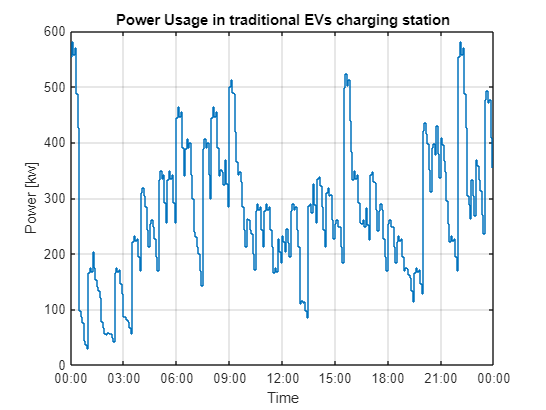

time = ChargerData.timestamp;
totalPower = ChargerData.ChargerPower.TotalkWhs;
totalPower = totalPower*(60*60); % convert kWh/s to kW
stairs(time, totalPower)
title('Power Usage in traditional EVs charging station')
datetick('x','HH:MM')
xlabel('Time')
ylabel('Power [kw]')
grid on

Set threshold value to start charge or discharge ESS.

pChgEss = 300;      % Start charging ESS after power usage drop below this value [kW]
pDscEss = 400;      % Start discharge ESS after power usage above this value [kW]

Set E-rate for ESS [Kw/h]. (assume charge and discharge rate is equal)

Erate = 100;

Set initail and limit SoC of Ess.

soc_init = 0.5;
soc_min = 0.1;
soc_max = 0.9;

ESS algolithm.